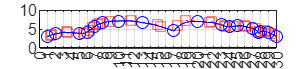

format long
x1=[1,2,5,6,7,8,10,13,17];
y1=[3,3.7,3.9,4.2,5.7,6.6,7.1,6.7,4.5];
x2=[17,20,23,24,25,27,27.7];
y2=[4.5,7.0,6.1,5.6,5.8,5.2,4.1];
x3=[27.7,28,29,30];
y3=[4.1,4.3,4.1,3.0];
v11=[1,-0.67];
v22=[3,-4];
v33=[0.33,-1.5];%输入点与导数值
A1=splinecoeff(x1,y1,v11);%获取三次样条系数矩阵
k1=[(A1(:,1))',v11(2)];%获取每点上的样条导数值
plot([0 30],[0,0],'k',[0 0],[0 8],'k');hold on
axis on;%设置坐标轴
set(gca,'fontsize',8,'xminortick','on');
set(gca,'XTick',0:1:30);
set(gcf,'unit','normalized','position',[0,0,0.9,0.3]);
grid on;%设置坐标轴网格
for i=1:(length(k1)-1)%将点进行分对画图
    k=[k1(i),k1(i+1)];%首末导数值
    x=[x1(i),x1(i+1)];%首末坐标值
    y=[y1(i),y1(i+1)];
    bezierplot(x,y,k);hold on%画出该对点的贝塞尔曲线
end
%对其他两组数据进行相同操作
A2=splinecoeff(x2,y2,v22);
k2=[(A2(:,1))',v22(2)];
for i=1:(length(k2)-1)
    k=[k2(i),k2(i+1)];
    x=[x2(i),x2(i+1)];
    y=[y2(i),y2(i+1)];
    bezierplot(x,y,k);hold on
end
A3=splinecoeff(x3,y3,v33);
k3=[(A3(:,1))',v33(2)];
for i=1:(length(k3)-1)
    k=[k3(i),k3(i+1)];
    x=[x3(i),x3(i+1)];
    y=[y3(i),y3(i+1)];
    bezierplot(x,y,k);hold on
end

function bezierplot(x,y,k)%画出贝塞尔曲线
%输入：首末数据点x,y向量，首末数据点处导数值k
%输出：画出该对点间对应的贝塞尔曲线
  t=0:0.01:1;
  r=(x(2)-x(1))/2;
  x=[x(1),x(1)+r./sqrt(k(1)^2+1),x(2)-r./sqrt(k(2)^2+1),x(2)];y=[y(1),y(1)+k(1)*r./sqrt(k(1)^2+1),y(2)-k(2)*r./sqrt(k(2)^2+1),y(2)]; 
  %为了控制平滑程度，让控制点与样条点距离保持0.6
  plot([x(1) x(2)],[y(1) y(2)],'r:',x(2),y(2),'rs');hold on
  plot([x(3) x(4)],[y(3) y(4)],'r:',x(3),y(3),'rs');hold on
  plot(x(1),y(1),'bo',x(4),y(4),'bo');hold on%画出样条点以及控制点
  bx=3*(x(2)-x(1)); by=3*(y(2)-y(1)); %样条方程
  cx=3*(x(3)-x(2))-bx;cy=3*(y(3)-y(2))-by;
  dx=x(4)-x(1)-bx-cx;dy=y(4)-y(1)-by-cy;
  xp=x(1)+t.*(bx+t.*(cx+t*dx));    % 霍纳方法
  yp=y(1)+t.*(by+t.*(cy+t*dy));
  plot(xp,yp,'b');hold on             %画出样条曲线        
end
function coeff=splinecoeff(x,y,v)%计算样条系数
%输入：数据点的x,y向量
%     以及两个斜率的向量v
%输出：系数矩阵
n=length(x);
v1=v(1);
vn=v(2);
A=zeros(n,n);%矩阵A是n*n
r=zeros(n,1);
for i=1:n-1%定义delta
    dx(i)=x(i+1)-x(i);dy(i)=y(i+1)-y(i);
end
for i=2:n-1%加载A矩阵
    A(i,i-1:i+1)=[dx(i-1),2*(dx(i-1)+dx(i)),dx(i)];
    r(i)=3*(dy(i)/dx(i)-dy(i-1)/dx(i-1));%右端端点
end
%设置端点条件
A(1,1:2)=[2*dx(1) dx(1)];r(1)=3*(dy(1)/dx(1)-v1);%钳制条件
A(n,n-1:n)=[dx(n-1),2*dx(n-1)];r(n)=3*(vn-dy(n-1)/dx(n-1));
coeff=zeros(n,3);
coeff(:,2)=A\r;%求解系数c
for i=1:n-1%求解b和d
    coeff(i,3)=(coeff(i+1,2)-coeff(i,2))/(3*dx(i));
    coeff(i,1)=dy(i)/dx(i)-dx(i)*(2*coeff(i,2)+coeff(i+1,2))/3;
end
coeff=coeff(1:n-1,1:3);
end